Load all relevant data:

% hpc
addpath(genpath('/proj/snic2022-5-384/users/x_albdv/reps/hca'));
addpath(genpath('/proj/snic2022-5-384/users/x_albdv/reps/discriminative_sequences'));
addpath(genpath('/proj/snic2022-5-384/users/x_albdv/reps/bargroupingprototype'));

% parpool('local');
dirName = '/proj/snic2022-5-384/users/x_albdv/data/discriminative/pyo';
% dirName = '/export/scratch/albertas/download_dump/S. pyogenes all data/onlyKymo/'; % folder with kymos
allTheoryFold = '/proj/dnadevdata/users/x_albdv/data/all/single/*.fasta';
refsNames = '/proj/snic2022-5-384/users/x_albdv/reps/discriminative_sequences/constants/pyo_theories.txt'; % using hca_cluster_run_demo and manual sorting based on folders
% refsNames =
% '/proj/snic2022-5-384/users/x_albdv/reps/discriminative_sequences/constants/pyo_t.txt';
% % from Anna

% scratchget_
% dirName = '/proj/snic2022-5-384/users/x_albdv/data/discriminative/pyo/';
% refsNames = '/export/scratch/albertas/download_dump/S. pyogenes all data/ClosestTheories/refs_pyo.txt';
% allTheoryFold = '/export/scratch/albertas/download_dump/single/*.fasta';


savedir = '/proj/dnadevdata/users/x_albdv/data/PYO/output/';

[kymoStructs,barN,twoList,bG,expPar,fastaFileF] = load_kymo_data_from_fold(dirName, refsNames,allTheoryFold,0.9:0.025:1.1,0);


ans =

    10     1


ans =

    11     2


ans =

     6     2


ans =

     2     2


ans =

    11     3


ans =

    11     1


ans =

     3     2


ans =

     2     1


ans =

     7     2


ans =

     5     1


ans =

     8     1


ans =

     6     1


ans =

     3     1


ans =

     4     2


ans =

     1     1


ans =

     8     2


ans =

     4     1


ans =

     2     3


ans =

     4     3


ans =

     7     3


ans =

     9     1


ans =

     6     3


ans =

     4     4


ans =

     7     1

Kymographs nr  were removed because they do not have enough time-frames
Starting kymo alignment...
Kymographs nr  were removed because they do not have enough time-frames
Starting kymo alignment...
Kymographs nr  were removed because they do not have enough time-frames
Starting kymo alignment...
Kymographs nr  were removed because they do not have enough time-frames
Starting kymo alignment...
Kymographs nr  were removed because they do not have enough time-frames
Star

Binding model: pregenerate result positions

sets = [];
[cI, bI, compI2, parl, allCoefsFit, m2, mA] = get_pseudotheory_positions(bG, twoList,expPar, fastaFileF, sets);

Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Elapsed time is 4.382022 seconds.
Finished computing free concentrations
Elapsed time is 4.473905 seconds.
Finished computing free concentrations
Elapsed time is 4.321285 seconds.
Finished computing free concentrations
Elapsed time is 4.477713 seconds.
Finished computing free con

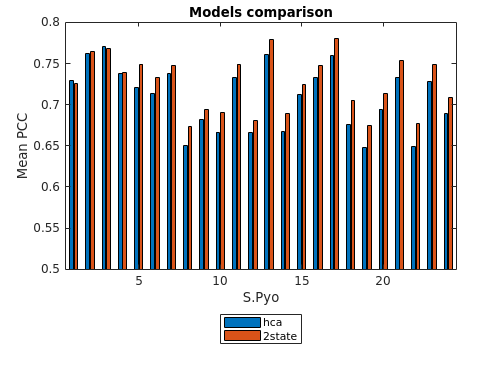

mtwo = cellfun(@(x) mean(x.maxcoef),cI,'UniformOutput',true);
% mA = cellfun(@(x) x.maxcoef(1),compI2,'UniformOutput',true);

% mA =cellfun(@(x) mean(cellfun(@(y) double(norminv(1-y.pval)),x).*cellfun(@(y) y.maxcoef(1),x)),compI2,'UniformOutput',true);

% score =cellfun(@(x) cellfun(@(y)  double(norminv(1-y.pval),x)>1.44,compI2,'UniformOutput',true);

 % stoufferScoresL = cellfun(@(x) double(norminv(1-x.pval)),compI2{expNr},'un',true);

plot_at_preference_model(bG,mA,mtwo)

Vary single parameter. Demonstration:

expNr = 1;
sets.nuF = 0.08; sets.nF = 0.2; % pval params from assembly paper
sets.comparisonMethod = 'mass_pcc'; % could use C++ version or UCR ED as well
sets.w = nan;

sF = 0.9:0.01:1.1;
sigma = 0.68; % 68?
kY = 10; % constant yoyo
kN = 30; % constant netropsin
psf = 370; % psf
cN = 6; % concentration netropsin
cY = 0.02; % concentration yoyo
ligandLength = 4;
gcSF = 1;
isC = 1;
bound = [0 5];
[sigma_opt] = run_single_parameter(gcSF,isC,sigma,kN,psf,cY,cN,kY,ligandLength,fastaFileF,expNr,expPar,...
    bI,cI,bound,sets)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           2   -7.614503e-01     0.000e+00     1.000e+00     0.000e+00     9.733e-03  
    1           4   -7.615479e-01     0.000e+00     1.000e+00     9.733e-03     1.031e-02  
    2           6   -7.621378e-01     0.000e+00     1.000e+00     5.153e-02     1.224e-02  
    3           9   -7.629132e-01     0.000e+00     7.000e-01     2.142e-01     2.375e-02  
    4          11   -7.630086e-01     0.000e+00     1.000e+00     1.413e-01     1.075e-02  
    5          13   -7.634046e-01     0.000e+00     1.000e+00     4.405e-02     6.705e-03  
    6          16   -7.635120e-01     0.000e+00     7.000e-01     5.110e-02     4.013e-03  
    7          18   -7.635374e-01     0.000e+00     1.000e+00     1.913e-02     1.094e-03  
    8          20   -7.635400e-01     0.000e+00     1.000e+00     4.099e-03     1.

sigma_opt = 0.4652


% parlist =  [gcSF,pxSize,nmpx,isC,sigma,kN,psf,cY,cN,kY,ligandLength];

[ZZ] = run_single_parameter_any(gcSF,isC,sigma_opt,kN,psf,cY,cN,kY,ligandLength,fastaFileF,expNr,expPar,...
    bI,cI,[100 500],7,sets)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           2   -7.635400e-01     0.000e+00     1.000e+00     0.000e+00     8.674e-05  
    1           4   -7.635400e-01     0.000e+00     1.000e+00     8.674e-05     8.674e-05  
    2           6   -7.635400e-01     0.000e+00     1.000e+00     4.337e-04     8.674e-05  
    3           8   -7.635402e-01     0.000e+00     1.000e+00     2.169e-03     8.674e-05  
    4          10   -7.635412e-01     0.000e+00     1.000e+00     1.084e-02     8.673e-05  
    5          12   -7.635459e-01     0.000e+00     1.000e+00     5.421e-02     8.667e-05  
    6          14   -7.635693e-01     0.000e+00     1.000e+00     2.708e-01     8.636e-05  
    7          16   -7.636848e-01     0.000e+00     1.000e+00     1.349e+00     8.483e-05  
    8          18   -7.642227e-01     0.000e+00     1.000e+00     6.627e+00     7.

ZZ = 488.7523

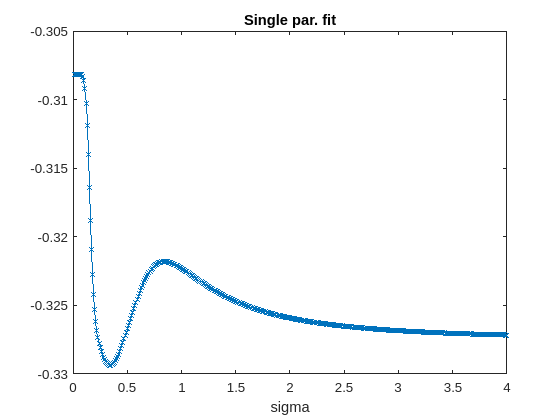

% 
[yoyoBindingProb] = get_yoyo_prob(kN,kY, cN,cY, sigma, ligandLength);
yoyofun = @(sigma)  get_yoyo_prob(kN,kY, cN,cY, sigma, ligandLength);
fun = @(xSv,ix1) -constfun_fit(yoyofun(xSv), cI{ix1},bI{ix1},fastaFileF{ix1},parl{ix1},sets);

vals = 0:0.01:4;
outv = zeros(1,numel(vals));
parfor i=1:numel(vals)
    outv(i) = fun(vals(i),expNr);
end




figure,plot(vals,outv,'x-')
hold on
% plot([yoyoBindingProb(idX) yoyoBindingProb(idX)],[min(outv) max(outv)],'red-')
title('Single par. fit')
xlabel('sigma')



fun = @(xSv,ix1) -constfun_fit(yoyofun(xSv), cI{ix1},bI{ix1},fastaFileF{ix1},parl{ix1},sets);

vals = 0:0.01:4;
outv = zeros(1,numel(vals));
parfor i=1:numel(vals)
    outv(i) = fun(vals(i),expNr);
end

sets.nuF = 0.08; sets.nF = 0.2; % pval params from assembly paper
sets.comparisonMethod = 'mass_pcc'; % could use C++ version or UCR ED as well
sets.w = nan;

sF = 0.9:0.01:1.1;
sigma = 0.5; % 68?
kY = 10; % constant yoyo
kN = 30; % constant netropsin
psf = 370; % psf
cN = 6; % concentration netropsin
cY = 0.02; % concentration yoyo
pxSize = nmpx/nmbp; % pixel size
ligandLength = 4;
yoyo = 26;
netrospin = 0.4;
parchangeId = 5; % scaling factor for binding constants
par = 0.68;%
gcSF = 1;
isC = 1;

% initial yoyo binding prob
[yoyoBindingProb] = get_yoyo_prob(kN,kY, cN,cY, sigma, ligandLength);
yoyofun = @(kY,sigma)  get_yoyo_prob(kN,kY, cN,cY, sigma, ligandLength);

mA = zeros(1,size(twoList,1));
sA = zeros(1,size(twoList,1));
mtwo= zeros(1,size(twoList,1));
sttwo= zeros(1,size(twoList,1));
mps= zeros(1,size(twoList,1));

% params for single set:
bI = {};
cI = {};
hc = {};
parl = {};
calcVals = zeros(size(twoList));
for expNr = 1:size(twoList,1);
    expNr
    barcodeGen = bG{expNr};
    nmbp = expPar{expNr}.nmbp;
    nmpx = expPar{expNr}.nmpx;
    [hcaSets,timestamp] = set_def();
    hcaSets.pixelWidthNm = nmpx;
    fastaFile = fastaFileF{expNr};
    hcaSets.folder{1} = fastaFileF{expNr} ;
    
    pxSize = nmpx/nmbp; % pixel size

    parlist = [gcSF,pxSize,nmpx,isC,sigma,kN,psf,cY,cN,kY,ligandLength];
    parlistcell = num2cell(parlist) ;
    
      [~,mid,~] = fileparts(hcaSets.folder{1} );
    delete(['seq_example',mid,'_',num2str(ligandLength) ,'.mat']);


    import Helper.run_comparison_fit;
    [cI{expNr}, rezI,   mtwo(expNr) , sttwo(expNr), sS,theoryStr,yoyoBindingProb,netropsinBindingConst] = ...
        run_comparison_fit(  barcodeGen,hcaSets.folder{1},parlistcell{:},parchangeId,par,sF,sets);

    mtwo = cellfun(@(x) mean(x.maxcoef),cI,'UniformOutput',true);

    import Core.rescale_barcode_data; % re-scale initial data
    [barGenRe] = rescale_barcode_data(barcodeGen,1,cI{expNr}.bestBarStretch);


    [mps(expNr)] = constfun_fit(yoyoBindingProb,cI{expNr},barGenRe,hcaSets.folder{1},parlistcell,sets);


    fun = @(kx,sx) -constfun_fit(yoyofun(kx,sx), cI{expNr},barGenRe,hcaSets.folder{1},parlistcell,sets);


    tol = 1e-11;
    options_all = optimoptions(@fmincon,'Display', 'iter', 'Algorithm', 'sqp', 'SpecifyObjectiveGradient',false, 'CheckGradient', false,  'OptimalityTolerance', tol, 'MaxFunctionEvaluations',20000 , 'StepTolerance', tol);
    
    xopt = [kY, sigma];

    lbounds = [zeros(1, length(xopt))];
    ubounds = [1000 10]; % no upper bounds on amplitudes

    [ZZ,FVAL,EXITFLAG,OUTPUT] = fmincon(@(x) fun(x(1),x(2)), xopt, [], [], [], [], lbounds, ubounds, [], options_all);
    calcVals(expNr,:) = ZZ;
end


Use all the datasets to find the best parameter value: sigma :

[yoyoBindingProb] = get_yoyo_prob(kN,kY, cN,cY, sigma, ligandLength);
yoyofun = @(sigma)  get_yoyo_prob(kN,kY, cN,cY, sigma, ligandLength);

fun = @(xSv,ix1) -constfun_fit(yoyofun(xSv), cI{ix1},bI{ix1},fastaFileF{ix1},parl{ix1},sets);

% fun(yoyoBindingProb,1)
% sum(lens([1 2 5 7 11 12 15 22]))

funM = @(x) -sqrt(sum(arrayfun(@(i) fun(x,i),1:24).^2))

funM = function_handle with value:
    @(x)-sqrt(sum(arrayfun(@(i)fun(x,i),1:24).^2))



tol = 1e-7;
options_all = optimoptions(@fmincon,'Display', 'iter', 'Algorithm', 'sqp', 'SpecifyObjectiveGradient',false, 'CheckGradient', false,  'OptimalityTolerance', tol, 'MaxFunctionEvaluations',20000 , 'StepTolerance', tol);

xopt = [0.4];

nvars = 1;
% no bounds ...
lbounds = [zeros(1, nvars)];
ubounds = [5*ones(1, nvars)]; % no upper bounds on amplitudes


[ZZ] = fmincon(@(x) funM(x), xopt, [], [], [], [], lbounds, ubounds, [], options_all);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           2   -4.088388e-01     0.000e+00     1.000e+00     0.000e+00     3.823e-02  
    1           4   -4.100346e-01     0.000e+00     1.000e+00     3.823e-02     2.350e-02  
    2           6   -4.106203e-01     0.000e+00     1.000e+00     6.099e-02     4.024e-03  
    3           8   -4.106391e-01     0.000e+00     1.000e+00

## Function: fit binding constants on all datasets

 [ZZ_fit_two] = fit_two_constants(kN, kY, cN,cY, sigma, ligandLength, cI, bI, fastaFileF, parl, sets)


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         257   -7.614503e-01     0.000e+00     1.000e+00     0.000e+00     4.290e-02  
    1         514   -7.767687e-01     0.000e+00     1.000e+00

Function fitting sigma and psf

Updated fit

[cI,bI,compI2, parl,allCoefsFit,m2,mA] = get_pseudotheory_positions(bG, twoList,expPar, fastaFileF, sets,481,0.7291);

Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Elapsed time is 1.052448 seconds.
Elapsed time is 1.121868 seconds.
Elapsed time is 1.020365 seconds.
Elapsed time is 1.027150 seconds.
Elapsed time is 1.012270 seconds.
Elapsed time is 1.026620 seconds.
Elapsed time is 1.082999 seconds.


mtwo = cellfun(@(x) mean(x.maxcoef),cI,'UniformOutput',true);

plot_at_preference_model(bG,mA,mtwo)


[ZZ_all_binding_constants,data] = fit_all_constants(kN, kY, cN,cY,  0.7291, ligandLength, cI, bI, fastaFileF, parl, sets);


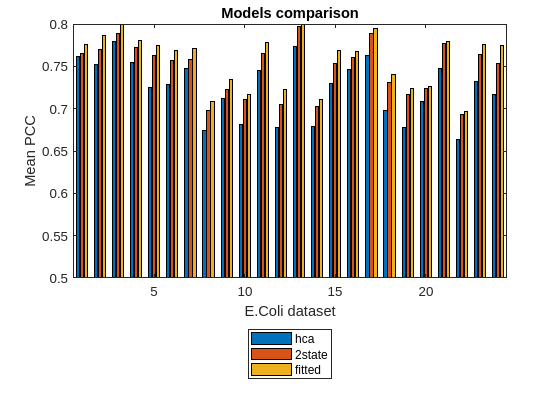

averageCC = zeros(1,length(bG));
%  sets.theory.stretchFactors = 0.8:0.025:1.2;
for expNr = 1:length(bG)
    import Core.rescale_barcode_data; % re-scale initial data
    [barGenRe] = rescale_barcode_data(bI{expNr},1,cI{expNr}.bestBarStretch);

    
%     [averageCC(expNr)] = constfun_fit(ZZ,cI{expNr},barGenRe,hcaSets.folder,parlistcell,sets);
    [averageCC(expNr)] = constfun_fit(ZZ_all_binding_constants,cI{expNr},barGenRe,data{expNr},parl{expNr},sets);


end

lengths = cellfun(@(x) length(x),bI);
figure,bar([mA(1:length(bG));mtwo(1:length(bG));averageCC]')
hold on
title('Models comparison')
legend({'hca','2state','fitted'},'location','southoutside')
xlabel('E.Coli dataset')
ylabel('Mean PCC')
ylim([0.5 0.8])

## Validation

% dirNameV = '/proj/dnadevdata/users/x_albdv/data/EHEC/EHEC data for local alignment/';
dirNameV = '/export/scratch/albertas/data_temp/Alignment/data/ehec/EHEC data for local alignment/';
refsNamesV = 'ehec_t.txt'

refsNamesV = 'ehec_t.txt'

[kymoStructsV,barNV,twoListV,bGV,expParV,fastaFileFV] = load_kymo_data_from_fold(dirNameV, refsNamesV,allTheoryFold,0.8:0.025:1.2,0);


ans =

     1     1


ans =

     1     2


ans =

     2     1


ans =

     3     1


ans =

     3     2


ans =

     4     1


ans =

     4     2


ans =

     5     1


ans =

     5     2


ans =

     6     1


ans =

     6     2


ans =

     6     3


ans =

     7     1


ans =

     7     2


ans =

     7     3


ans =

     8     1


ans =

     8     2


ans =

     8     3


ans =

     8     4



Error using imfinfo
Unable to determine file format.

Error in CBT.Hca.Import.add_kymographs_fun (line 54)
            if length(imfinfo(fullfile(sets.kymosets.kymofilefold{keep(i)},kymoStructs{i}.name))) == 3

Error in Core.load_kymo_data (




[cIV,bIV,compI2V, parlV,allCoefsFitV,m2V,mAV] = get_pseudotheory_positions(bGV, twoListV,expParV, fastaFileFV, sets,ZZ(2),ZZ(1));

mtwoV = cellfun(@(x) mean(x.maxcoef),cIV,'UniformOutput',true);

plot_at_preference_model(bGV,mAV,mtwoV,'EHEC')

dataV = cell(1,length(bIV));
for i=1:length(bIV)
    [~,mid,~] = fileparts(fastaFileFV{i});
    dataV{i} = load(['seq_example',mid,'_',num2str(parlV{i}{11}),'_',num2str(parlV{i}{2}) ,'.mat']); % add nmpx att the end
end


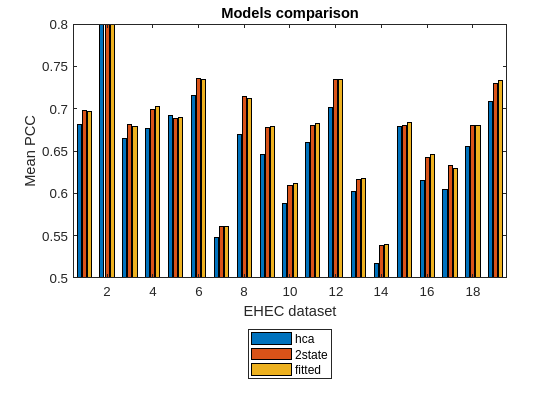



averageCCv = zeros(1,length(bIV));
%  sets.theory.stretchFactors = 0.8:0.025:1.2;
for expNr = 1:length(bIV)
    import Core.rescale_barcode_data; % re-scale initial data
    [barGenRe] = rescale_barcode_data(bIV{expNr},1,cIV{expNr}.bestBarStretch);

    
%     [averageCC(expNr)] = constfun_fit(ZZ,cI{expNr},barGenRe,hcaSets.folder,parlistcell,sets);
    [averageCCv(expNr)] = constfun_fit(ZZ_all_binding_constants,cIV{expNr},barGenRe,dataV{expNr},parlV{expNr},sets);


end

lengths = cellfun(@(x) length(x),bIV);
figure,bar([mAV(1:length(bIV));mtwo(1:length(bIV));averageCCv]')
hold on
title('Models comparison')
legend({'hca','2state','fitted'},'location','southoutside')
xlabel('EHEC dataset')
ylabel('Mean PCC')
ylim([0.5 0.8])